# ANOVA Example

Andrew Brown

GEEN 3853

10/19/2020

## INTRODUCTION

An airline has a toll-free phone number that they use for reservations. Sometimes callers have to be placed on hold. The airline conducted a randomized experiment to determine if there was a significant difference in how long a caller would remain on hold depending on the content of the music/sound that is playing on the call. The airline randomly selected one out of every 1000 calls to be placed on hold with either an advertisement of current promotions, muzak (elevator music), or classical music playing. In total, 15 callers were sampled for this study. In the dataset for this problem, each column is the number of minutes that the random caller remained on the line until they hung up for each type of recorded message. This dataset comes from Statistics: The Art and Science of Learning from Data by Alan Agresti and Christine Franklin, and was accessed via StatCrunch.com.

## PREP WORKSPACE

clear all
close all
clc

## LOAD THE DATA

We first load the dataset titled "NoDifference"

opts = delimitedTextImportOptions("NumVariables", 2);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["HoldTime_m", "TypeSound"];
opts.VariableTypes = ["double", "string"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, "TypeSound", "EmptyFieldRule", "auto");

% Import the data
raw = readtable("C:\Users\andre\OneDrive\Documents\MATLAB\GEEN 3583\AirlineHoldMusic.csv", opts);
%% Clear Import Options
clear opts

## CLEAN AND SUBSET THE DATA

View the dataset and perform necessary cleanup.

%View the first five rows of all columns
raw(:,:)

ans = 15×2 table
    HoldTime_m       TypeSound   
    __________    _______________

         5        "Advertisement"
         1        "Advertisement"
        11        "Advertisement"
         2        "Advertisement"
         8        "Advertisement"
         0        "Muzak"        
         1        "Muzak"        
         4        "Muzak"        
         6        "Muzak"        
         3        "Muzak"        
        13        "Classical"    
         9        "Classical"    
         8        "Classical"    
        15        "Classical"    
         7        "Classical"    


%We want all rows and columns.
advertisement = table2array(raw(1:5,1));
muzak = table2array(raw(6:10,1));
classical = table2array(raw(11:15,1));
holdTime = cat(2,advertisement,muzak,classical)

holdTime =      5     0    13
     1     1     9
    11     4     8
     2     6    15
     8     3     7


data = cat(1,advertisement,muzak,classical);
zdata = [0;0;0;0;0;1;1;1;1;1;2;2;2;2;2];
soundType = {'Advertisement', 'Muzak', 'Classical'};

# DESCRIPTIVE STATISTICS

## DESCRIPTIVE STATISTICS - VISUAL

### Histograms

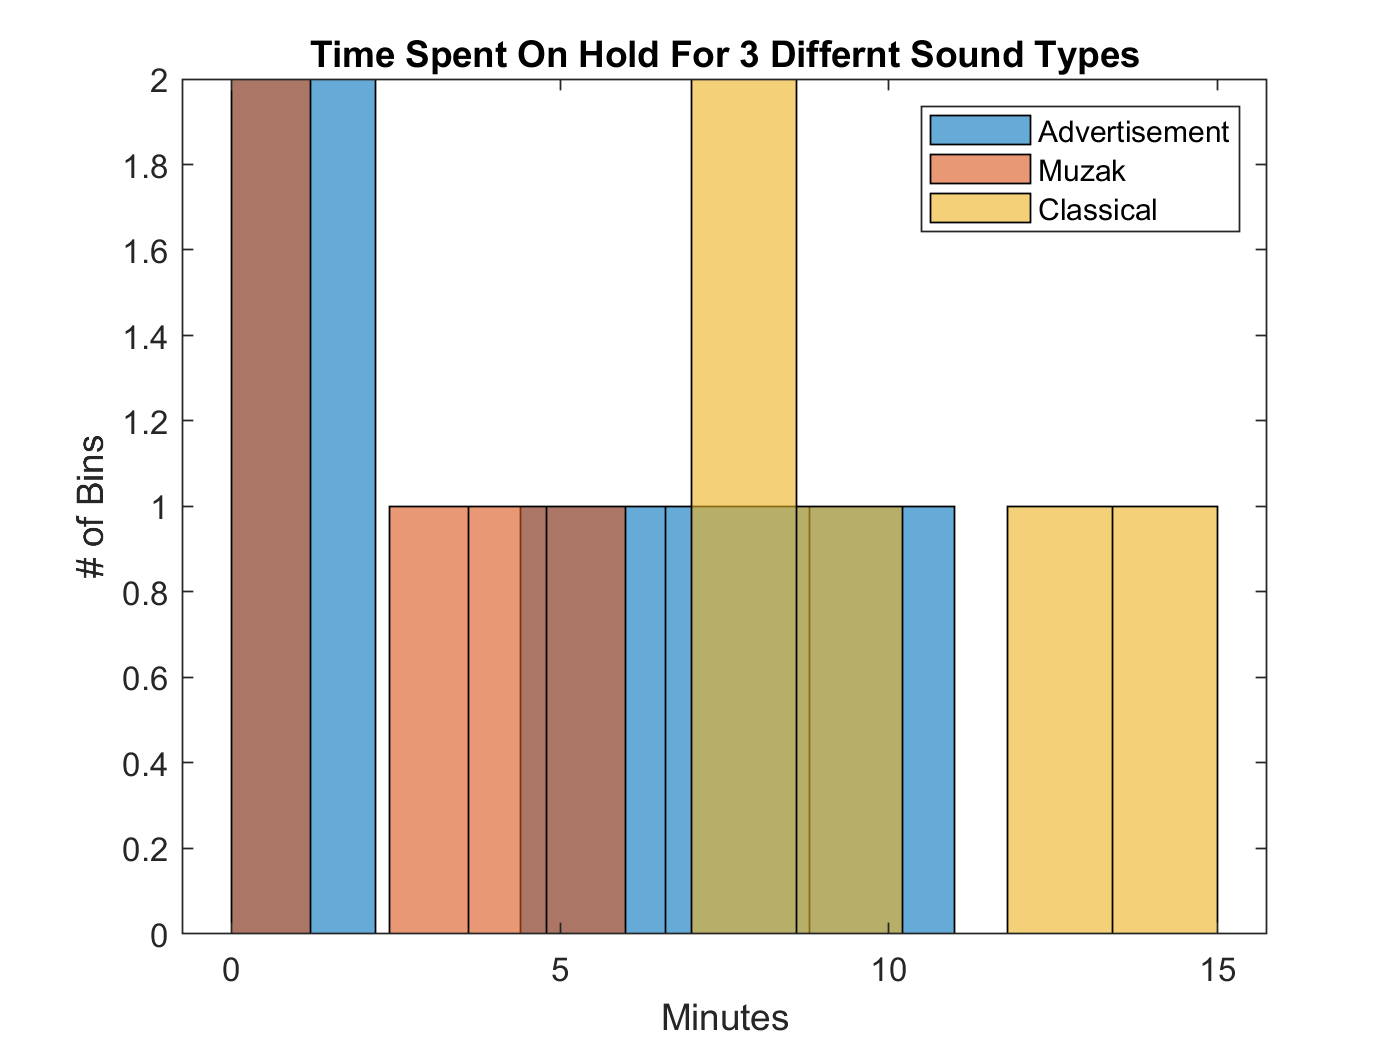

%Obtain the histogram plot of the dataset
figure
histogram(advertisement,'NumBins',5)
hold on
histogram(muzak,'NumBins',5)
histogram(classical,'NumBins',5)
hold off

xlabel('Minutes')
ylabel('# of Bins')
legend("Advertisement", "Muzak", "Classical")
title('Time Spent On Hold For 3 Differnt Sound Types')


% figure
% histogram(test1,'Normalization','pdf');


### Probability Density Functions

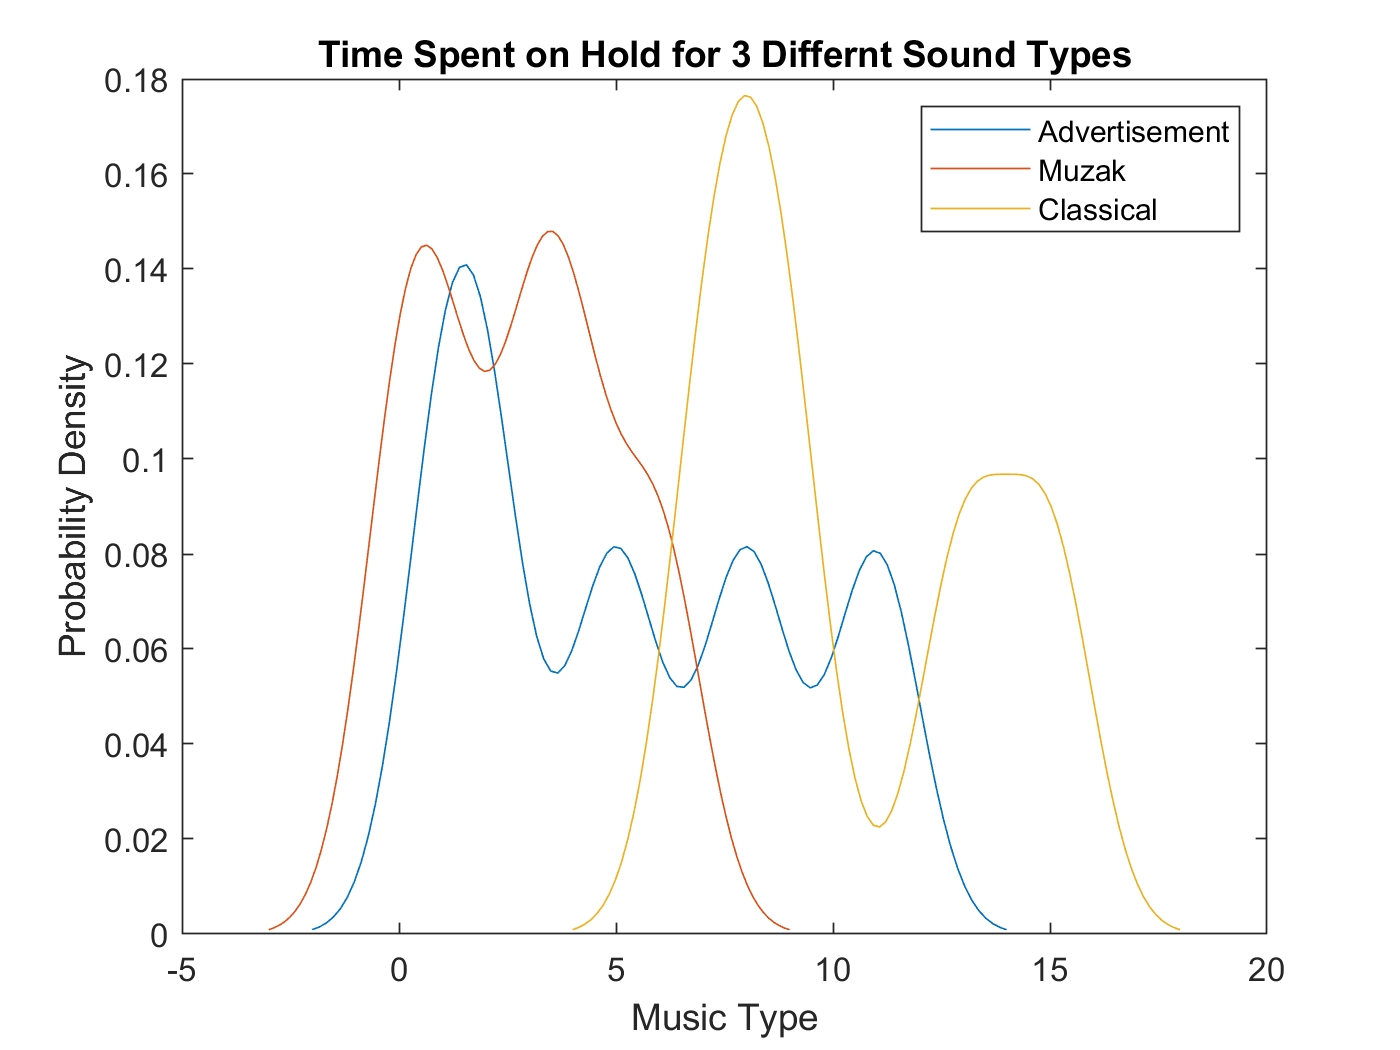

%'Bandwidth' adjusts how much filtering is applied: larger # = more
%filtering
figure
ksdensity(advertisement,'Bandwidth',1);
hold on
ksdensity(muzak,'Bandwidth',1);
ksdensity(classical,'Bandwidth',1);
hold off


xlabel('Music Type')
ylabel('Probability Density')
legend('Advertisement','Muzak','Classical')
title('Time Spent on Hold for 3 Differnt Sound Types')

#### Take Aways

From the histograms/pdfs, it looks like with regards to time spent on hold, Classical > Advertisement > Muzak.

### Boxplots

Boxplots are a great way to compare median, IQR (1st to 3rd), and outliers.  In Matlab, the whiskers extend to the farthest data points that are not considered outliers.  The default setting for Matlab is that an outliers is any value more extreme than 1.5*(Q3-Q1) away from the Q1 or Q3 value.

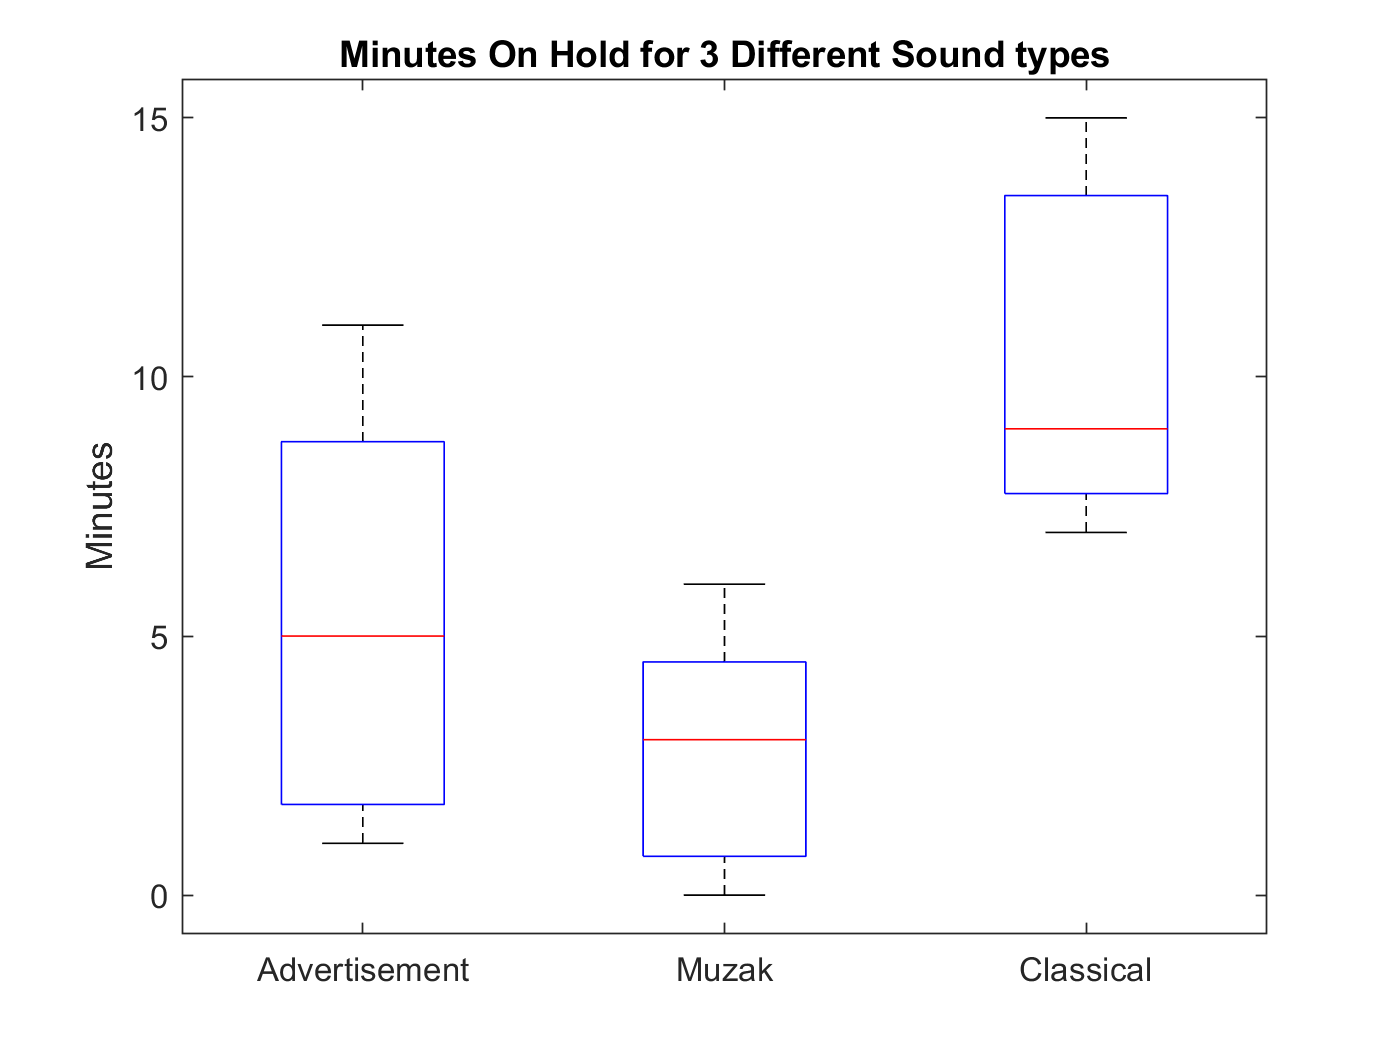

figure
boxplot(holdTime,"Labels",{'Advertisement','Muzak','Classical'})
ylabel ('Minutes')
title('Minutes On Hold for 3 Different Sound types')
hold off

#### Take Aways

These box plots also suggest that with regards to time people stay on hold, Classical > Advertisement > Muzak, but it is clear that Muzak and Advertisement have a lot of overlap, and Muzak has the lowest standard deviation from its mean.

### Scatterplots

If appropriate, plot the data relative to one another.  

This doesn't make sense for this data/problem.

## DESCRIPTIVE STATISTICS - NUMERIC

## Univariate

%Set up a results table
descrStats = table();

descrStats.Mean = mean(holdTime)';
descrStats.SD = std(holdTime)';
descrStats.Med = median(holdTime)';
descrStats.Max = max(holdTime)';
descrStats.Min = min(holdTime)';
descrStats.IQR = iqr(holdTime)';

%Row Labels
descrStats.Properties.RowNames = {'Advertisement','Muzak','Classical'};

descrStats

descrStats = 3×6 table
                     Mean      SD      Med    Max    Min    IQR 
                     ____    ______    ___    ___    ___    ____

    Advertisement     5.4    4.1593     5     11      1        7
    Muzak             2.8    2.3875     3      6      0     3.75
    Classical        10.4    3.4351     9     15      7     5.75


#### Take Aways

The numeric, univariate statistics also suggest that with regards to average time spent on hold, Classical > Advertisement > Muzak. The other variables also generally follow this pattern.

### Bivariate

The most common bivariate statistic that we will utilize is the correlation coefficient.

This doesn't make sense to compute for this data/problem.

# INFERENTIAL STATISTICS

Our ultimate goal is to test the difference in means.  However, to do that, we need to first test the normality of the groups.  We also need to know if the groups have equal or unequal variance so that we know what t-test to use in our test of location.

## TEST OF NORMALITY

For a two-sample, independent test, we need to test the normality of each group.

Underlying Assumptions of the Test :

- The data are continuous.

- The data are from a sample that was randomly drawn from a process/population.

Method: Anderson-Darling and Normality Plot

Step 1 : (Note that a non-directional test is assumed.)

H0 :$\gamma$_3 = 0 and $\gamma$_4 = 0 for all groups

H1 : $\gamma$_3 $\not=$ 0 and $\gamma$_4 $\not=$ 0 for some/all groups

Step 2: Alpha level; i.e., significance level, or how much Type I error you are willing to make

alpha1 = 0.05

alpha1 = 0.0500

Step 3 : We will use the AD test statistic.

Step 4 : We will use the AD RSD

Step 5 : State the Critical Value for Rejecting the Null Hypothesis

    Quantitative: Reject H0 if any p-value < $\alpha$ 

Step 6 : Calculations

### Normality Plot

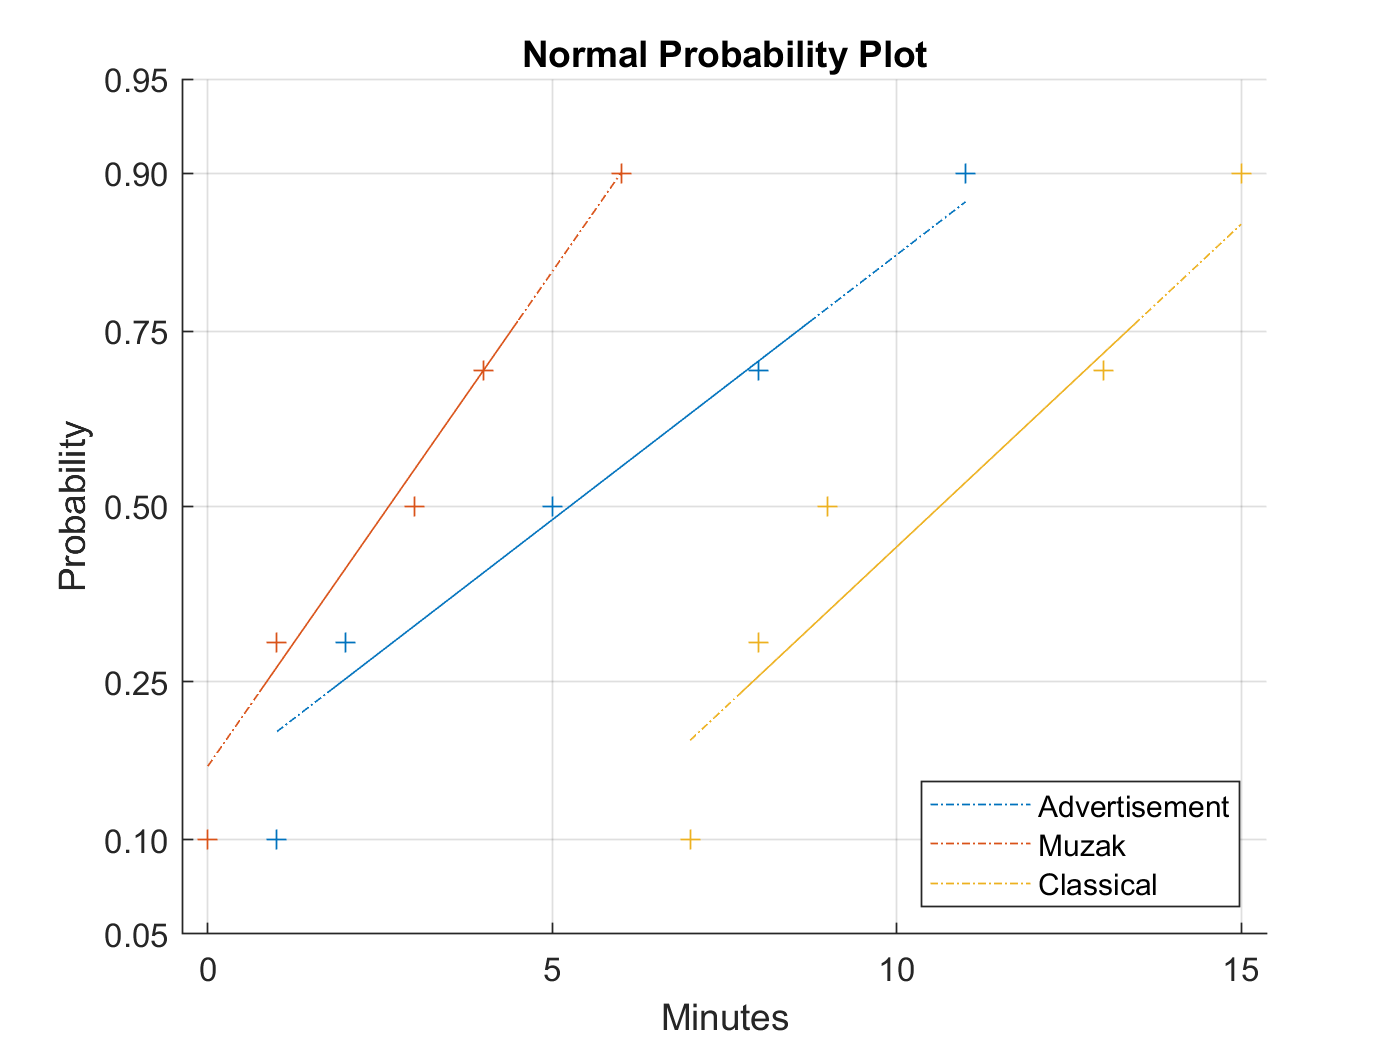

figure
normplot(holdTime)
legend('Advertisement','Muzak','Classical','Location','southeast')
xlabel('Minutes')

**Take Aways**

This normality plot provides further evidence to the previously stated hypotheses and shows that all 3 populations roughly follow ttheir respective linear regression lines, showing normality.

### Anderson-Darling Statistic

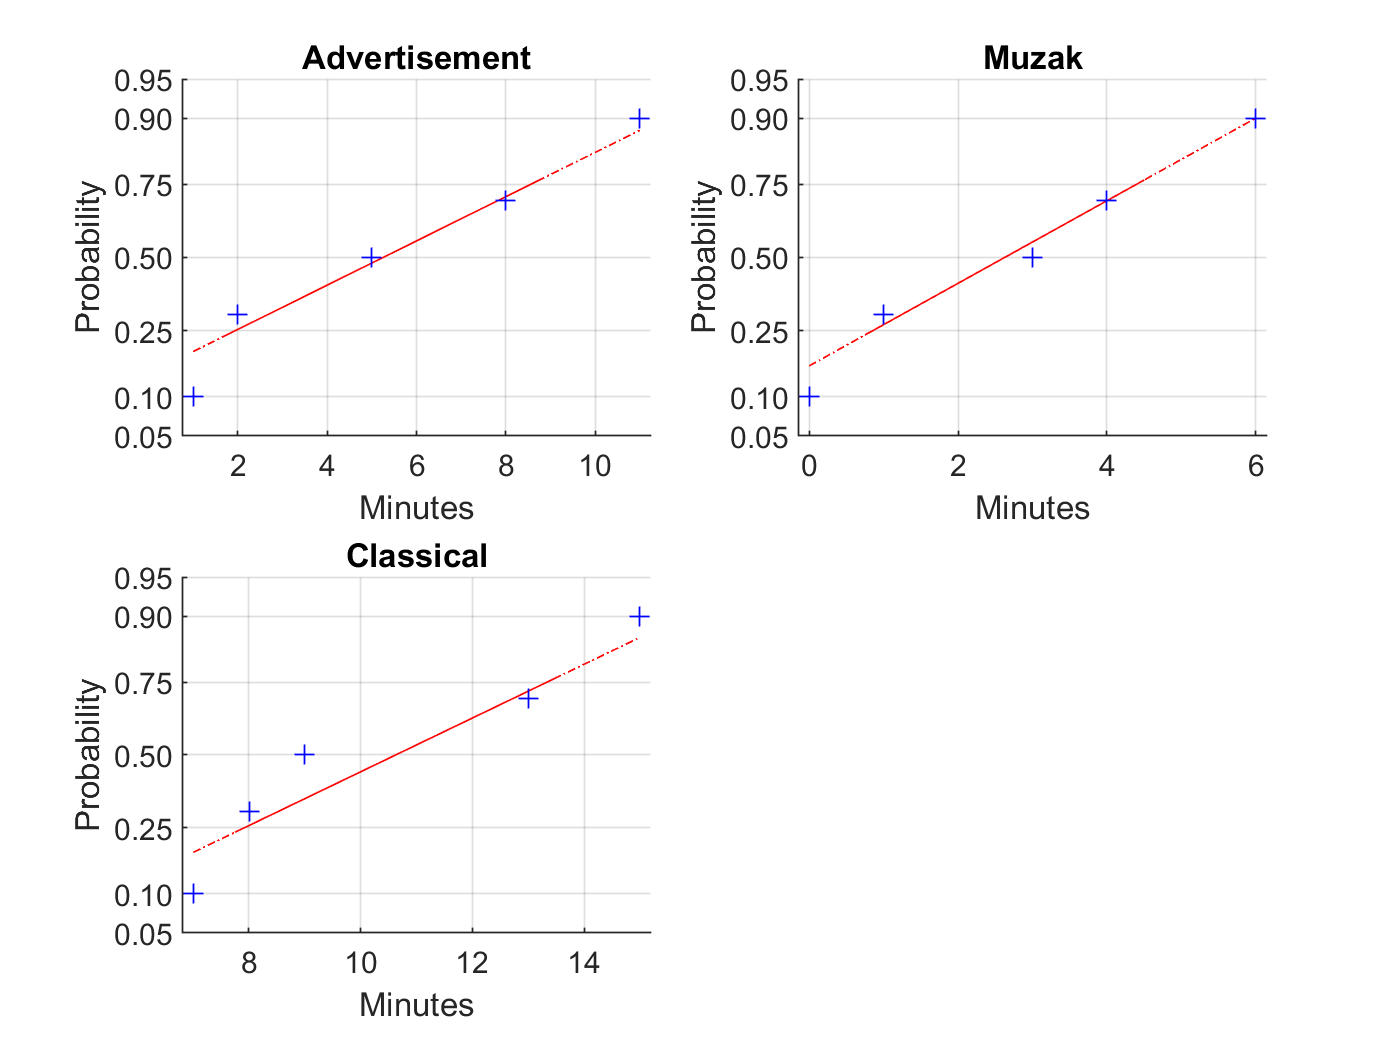

%data_labels = {'Advertisement','Muzak','Classical'};

figure
for i=1:3
    subplot(2,2,i)
    normplot(holdTime(:,i)) %quanlitative check
    title(soundType(i))
    xlabel('Minutes')

    %anderson-darling test for normality
    % Ho: sample is normal, H1: sample is non-normal
    [h1_norm(i),p1_norm(i), AD_stat(i), cv_norm(i)] = adtest(holdTime(:,i));
end

h1_norm

h1_norm = 1×3 logical array
   0   0   0


p1_norm

p1_norm =     0.8078    0.9350    0.4389


Take-away: 

### Decision

Step 7a) Decision : **Fail to Reject H0** (for both groups)

7b) p = see above

7c) We have sufficient statistical evidence to infer that the populations from which these data were randomly sampled are

symmetrical and mesokurtic, and, therefore, may be approximated by the Normal distribution. 

Based on n = 5, the A-D tests are appropriate for this analysis.

n = size(holdTime,1) 

n = 5

Only one sample size variable is appropriate for this problem because all groups have equal sample size.

## TEST OF VARIANCE

The test of variance will tell us what t-test to use in the test of location.

Underlying Assumptions of the Test :

- The data are continuous.

- The data are from a sample that was randomly drawn from a process/population.

- The data are normally distributed (all groups).

Method: For a three-sample, independent test:  Levene Test

Step 1 : (Note that a non-directional test is assumed.)

H0 : variance is equal for all groups

H1: variance is not equal across all groups

Step 2: Alpha level; i.e., significance level, or how much Type I error you are willing to make

    We will use the same alpha as that for the normality test

alpha1

alpha1 = 0.0500

Step 3 : We will use the F statistic

Step 4 : We will use the RSD for F with (n1-1, n2-1) degrees of freedom

Step 5 : State the Critical Value for Rejecting the Null Hypothesis

    We will reject the null if p < alpha or F_stat < F_crit

Step 6: Calculations

### Levene test for Variance

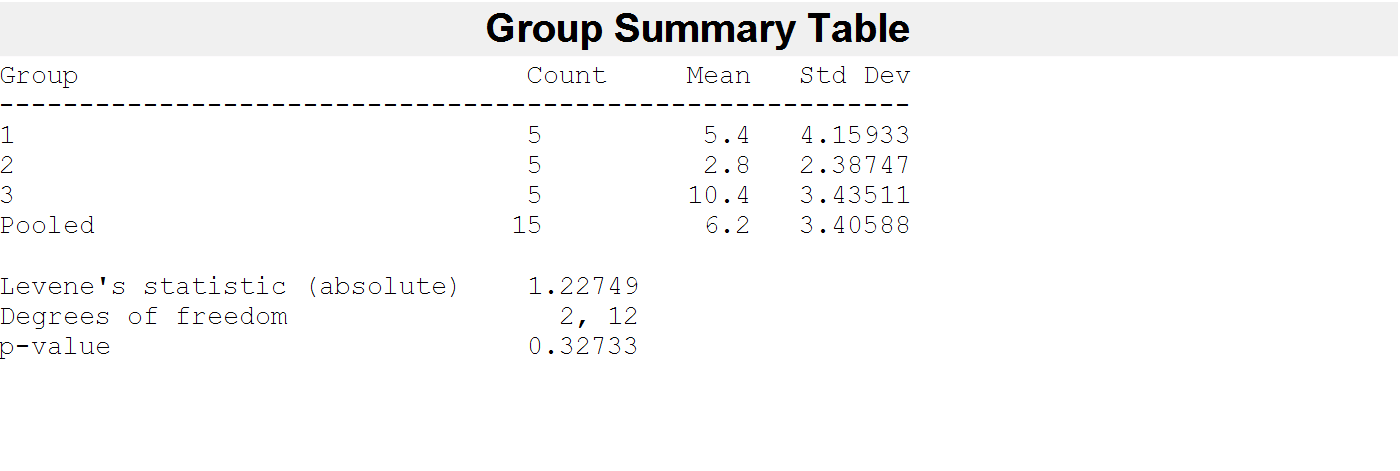

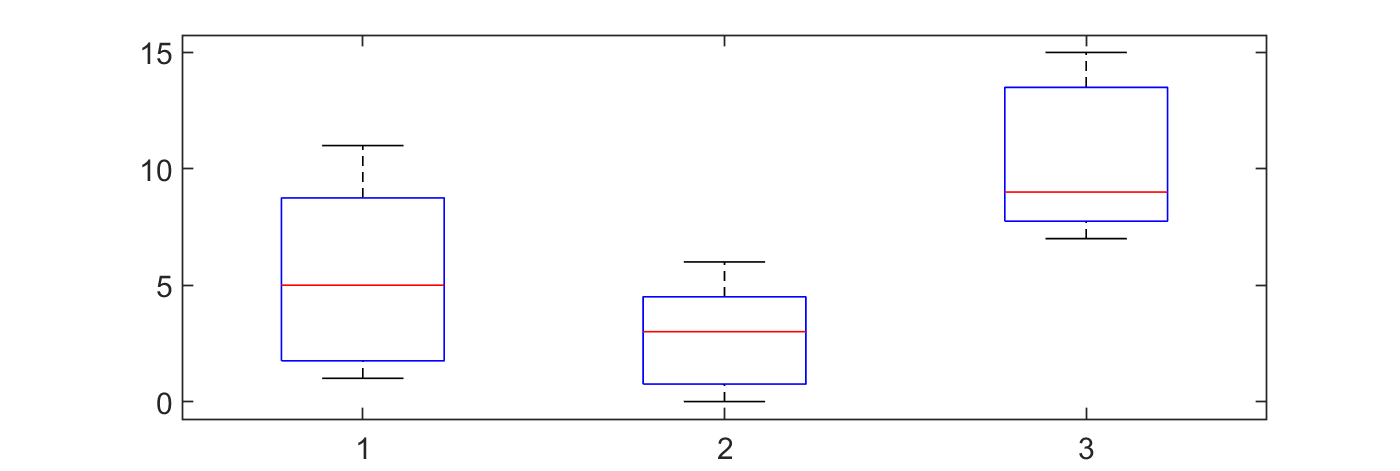

[p_var,STATS_var] = vartestn(holdTime,'TestType','LeveneAbsolute');

Notice that the p-value is greater than alpha.

### Decision

Step 7a) Decision : ** Fail to Reject H0**

7b) p = 0.327 (greater than alpha)

7c) We have sufficient statistical evidence to infer that the variances of the populations from which these samples were drawn are **equal.**

7d) Appropriate Point Estimates (Report  only if variance is the goal of the test)

7e) Appropriate Interval Estimates (Report only if variance is the goal of the test)

## TEST OF LOCATION

Underlying Assumptions of the Test :

- The data are continuous.

- The data are from a randomly-drawn sample from a process/population (independent specimens).

- Indep., Equal Var.: Homogeneity of variance (equal variance) may be known or assumed. 

Method: 1-Way ANOVA (1 Factor)

Step 1 : (Note that a non-directional test is assumed.)

H0 : All means are equal 

H1: All means are not equal (at least two means are statistically different)

Step 2: Alpha level; i.e., significance level, or how much Type I error you are willing to make

    We will use the same alpha as that for the normality test

alpha1

alpha1 = 0.0500

Step 3 : We will use the F statistic

Step 4 : We will use the RSD for F with 2 and 12 df

Step 5 : State the Critical Value for Rejecting the Null Hypothesis

    We will reject the null if p < alpha 

Step 6: Calculations

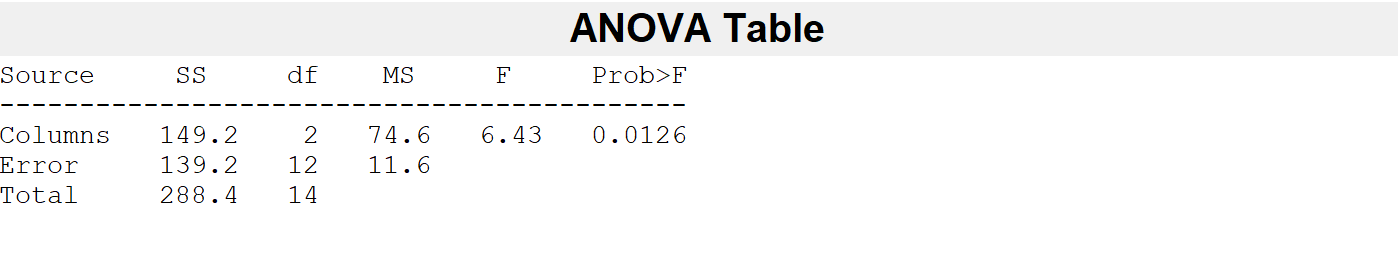

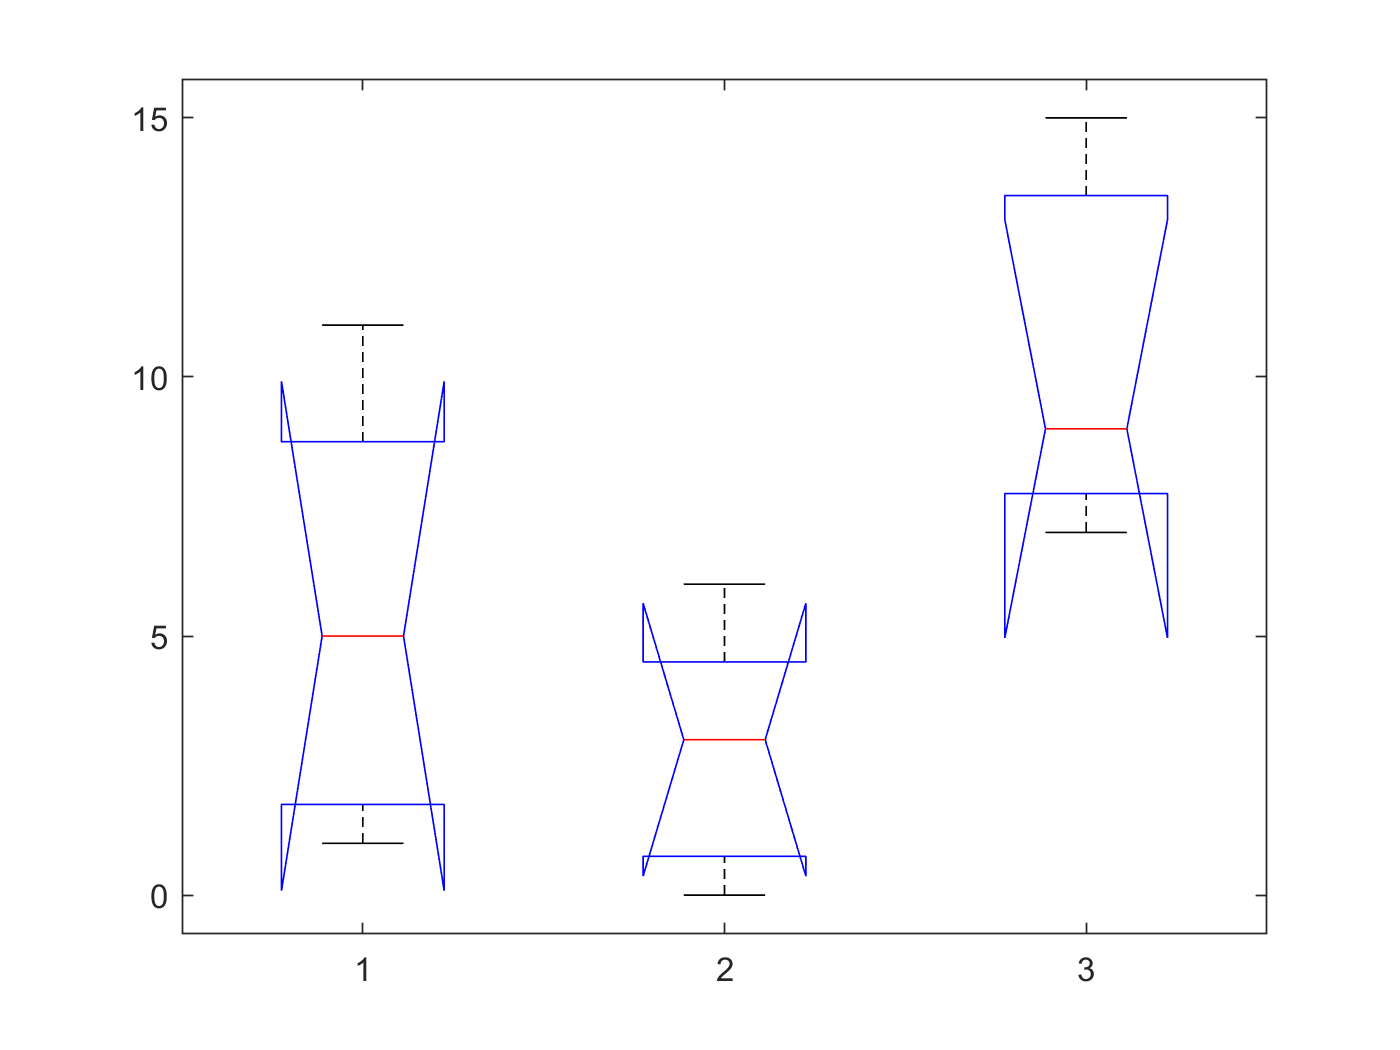

[p_ANOVA,ANOVATABLE,STATS_ANOVA] = anova1(holdTime);

The p-value is less than alpha. 

### Decision

Step 7a) Decision : **Reject H0**

7b) p = 0.0126 (p less than alpha)

7c) We have sufficient statistical evidence to infer that one or more of the means of the populations from which these samples were drawn are unequal. 

7d) Appropriate Point Estimates

    *M_Advertisement = *5.4 minutes*  |  M_Muzak = *2.8 minutes*  |  M_Classical = *10.4 minutes

7e) Appropriate Interval Estimate(s)

%extremes_advertisement = [1, 11];
%extremes_muzak = [0, 6];
%extremes_classical = [7, 15];
%CI_Advertisement = paramci(extremes_advertisement)
%CI_Muzak = paramci(extremes_muzak)
%CI_Classical = paramci(extremes_classical)

7f) Effect Size

FOR ANOVA: We will need to find which groups are different, if we reject the null.  We do that through post-hoc analysis.

## Post-Hoc Analysis

Tukey HSD b/c Variences are equal and populations are balanced.

prtrng=cdfTukey(15,12,15)

prtrng = 0.9974

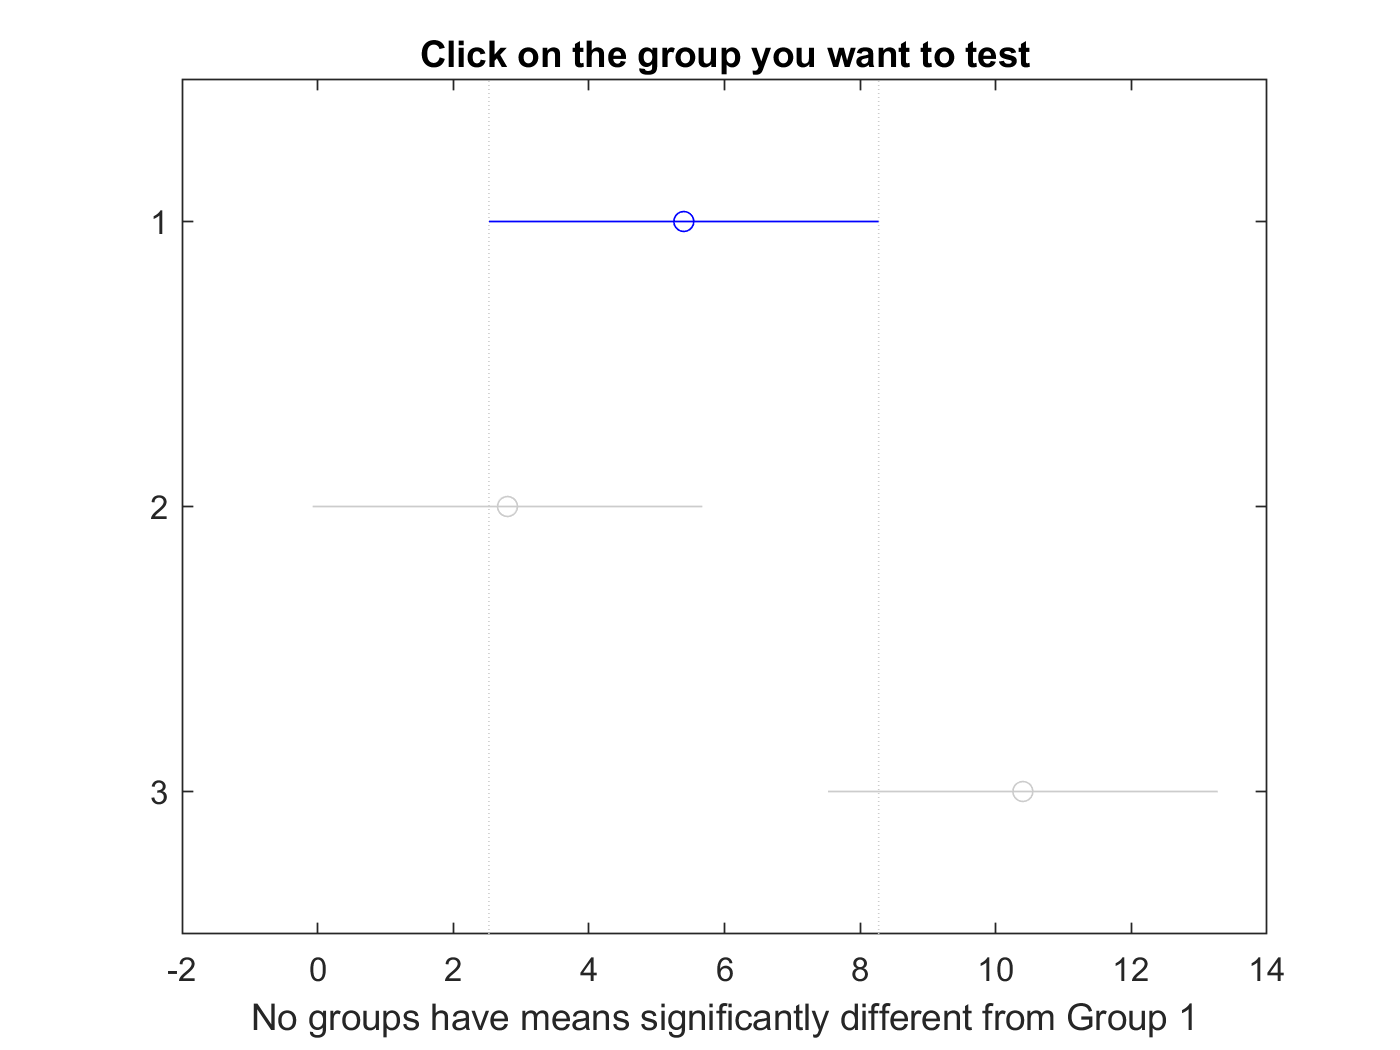

c =     1.0000    2.0000   -3.1468    2.6000    8.3468    0.4716
    1.0000    3.0000  -10.7468   -5.0000    0.7468    0.0910
    2.0000    3.0000  -13.3468   -7.6000   -1.8532    0.0107


m =     5.4000    1.5232
    2.8000    1.5232
   10.4000    1.5232


h =   Figure (boxplot) with properties:

      Number: 9
        Name: 'Multiple comparison of means'
       Color: [1 1 1]
    Position: [489 143 560 420]
       Units: 'pixels'

  Show all properties


nms = 3×1 char array
    '1'
    '2'
    '3'


[c,m,h,nms] = multcompare(STATS_ANOVA,'ctype','hsd','display','on')

### Effect Size

[STATS_MES, varargout_mes] = mes1way(data,{'eta2','partialeta2','omega2','partialomega2'},'group',zdata);

summaryTable = 4×18 cell array
    {'source'        }    {'SS'      }    {'df'}    {'MS'     }    {'F'       }    {'p'       }    {'eta2'    }    {'ci_lo'   }    {'ci_up'   }    {'partialeta2'}    {'ci_lo'   }    {'ci_up'   }    {'omega2'  }    {'ci_lo'   }    {'ci_up'   }    {'partialomega2'}    {'ci_lo'   }    {'ci_up'   }
    {'between-groups'}    {[149.2000]}    {[ 2]}    {[74.6000]}    {[  6.4310]}    {[  0.0126]}    {[  0.5173]}    {[  0.0363]}    {[  0.6958]}    {[     0.5173]}    {[  0.0363]}    {[  0.6958]}    {[  0.4200]}    {[ -0.1150]}    {[  0.6292]}    {[       0.4200]}    {[ -0.1150]}    {[  0.6292]}
    {'within-groups' }    {[139.2000]}    {[12]}    {[11.6000]}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double   }    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double     }    {0×0 double}    {0×0 double}
    {'total'         }    {[288.4000]}    {[14]}    {[20.6000]}    {0×0 double}  

## CONCLUSION

Ultimately, we learned quite a few different things about our samples. First, from the Anderson-Darling Test we learned that all 3 populations can be assumed to be normally distributed. Second, we learned from the Levene test, that the variances between the 3 groups of music were statistically equal. Third, we learned from the 1-Way ANNOVA that one or more of our populations have a mean that is statistically different. Fourth, we learned from our Tukey HSD Test in our Post-Hoc Analysis that only the Muzak mean was statistically different (lower) than the Classical mean. All other mean differences were not statistically different. Finally, we learned from our omega squared values that 42% of the overall variance comes from the difference in the means between the groups. Ultimately, if choosing between the 3 types of music, you would not want to choose Muzak, and statistically speaking, despite the larger mean of Classical, there would be no difference between choosing Classical music and Advertisements, if your goal is to keep people on hold for longer.